# MEMS resonator using the Multi-Point Constraint method

MPC example for some MEMS gyroscope prototype (Test Structure #, TS# in short). A similar structure to TS1 has been studied in:

- Marconi, J., Tiso, P., Quadrelli, D.E. *et al.* A higher-order parametric nonlinear reduced-order model for imperfect structures using Neumann expansion. *Nonlinear Dyn* **104**, 3039–3063 (2021). [https://doi.org/10.1007/s11071-021-06496-y](https://doi.org/10.1007/s11071-021-06496-y)

A similar structure to TS4 has been studied in:

- J. Marconi, G. Bonaccorsi, D. Giannini *et al.* Exploiting Nonlinearities for Frequency-Matched MEMS Gyroscopes Tuning, *IEEE International Symposium on Inertial Sensors and Systems* (INERTIAL 2021). [https://doi.org/10.1109/INERTIAL51137.2021.9430478](https://doi.org/10.1109/INERTIAL51137.2021.9430478)

- Saccani, A., Marconi, J. & Tiso, P. Sensitivity analysis of nonlinear frequency response of defected structures. *Nonlinear Dyn* **111**, 4027–4051 (2023). [https://doi.org/10.1007/s11071-022-08064-4](https://doi.org/10.1007/s11071-022-08064-4)

clear; close all; clc
TS = 1;

*Class path:* `"../src/misc/MultiPointConstraint.m"`

For a tutorial on the `MultiPointConstraint` class, refer to "`../examples/Mechanical/1D/mpc/demo_mpc.mlx`"

## Model definition

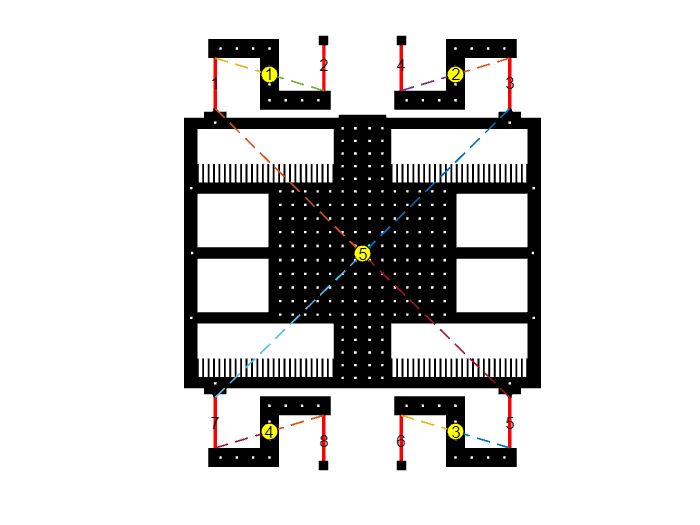

% geometry and area properties
switch TS
    case 1
        model = mems_ts1_model;
        
        % number of beams and elements per beam
        nb = 8; 
        model.nElements = 10 * ones(nb,1);
        
        % beam section properties
        model.thickness = 20;         % [um] same thickness for the whole model (masses and beams)
        model.width = 4.5*ones(nb,1); % [um] define the width for each beam
    case 3
        model = mems_ts3_model;
        
        % number of beams and elements per beam
        nb = 5*4; 
        model.nElements = 10 * ones(nb,1);
        
        % beam section properties
        model.thickness = 20;         % [um] same thickness for the whole model (masses and beams)
        model.width = 4.5*ones(nb,1); % [um] define the width for each beam
    case 4
        model = mems_ts4_model;

        % number of beams and elements per beam
        nb = 16;
        model.nElements = [10*ones(4,1); repmat([10 3 10]',4,1)];
        
        % beam section properties
        model.thickness = 20;         % [um] same thickness for the whole model (masses and beams)
        model.width = [4*ones(4,1); repmat([3.4 15 3.4]',4,1)]; % [um] define the width for each beam
end

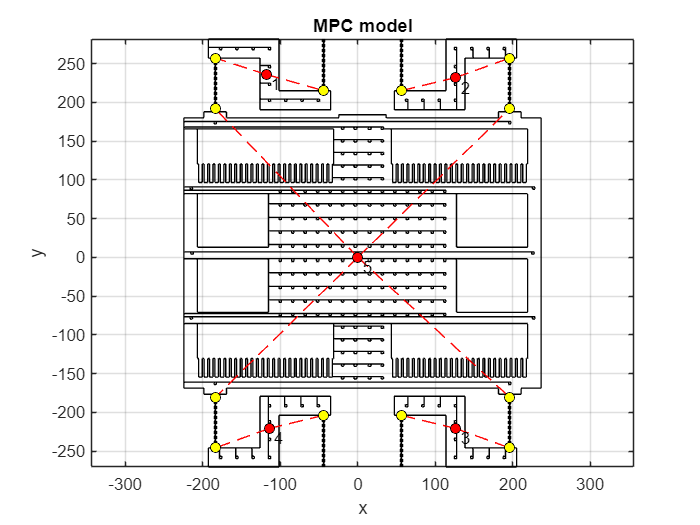

% material properties (polysilicon)
model.E   = 148e3;    % [MPa] Young's modulus
model.rho = 2.33e-15; % [Kg/um³] density
model.nu  = 0.23;     % [-] Poisson modulus

obj = mems_assembly(model, true);

disp(obj)

  MultiPointConstraint with properties:

             mpc: [12×2 double]
     masterNodes: [5×5 double]
            Tmpc: [267×231 double]
      masterDOFs: [15×3 double]
              Mm: {5×1 cell}
              Km: {[3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]}
            PLOT: [1×1 struct]
          nNodes: [1×1 struct]
           nDOFs: [1×1 struct]
    parallelized: 0
            Mesh: [1×1 Mesh]
            DATA: []


## Eigenvalues and Eigenvectors

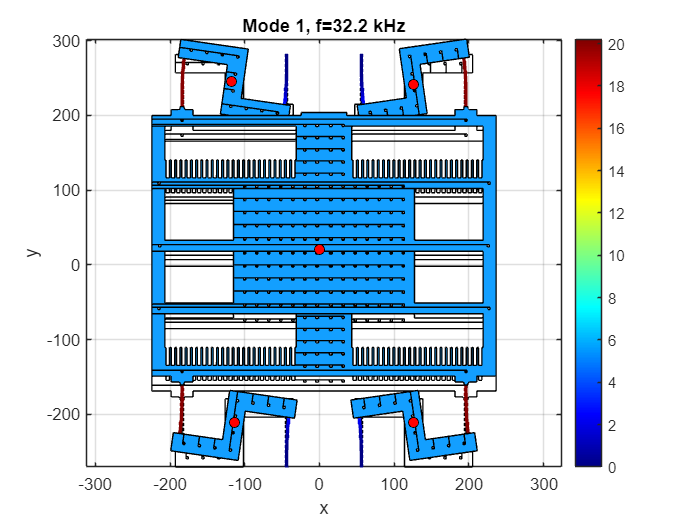

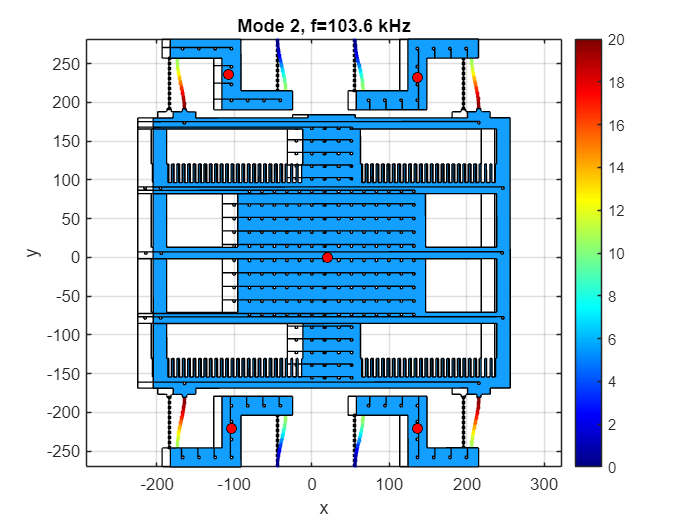

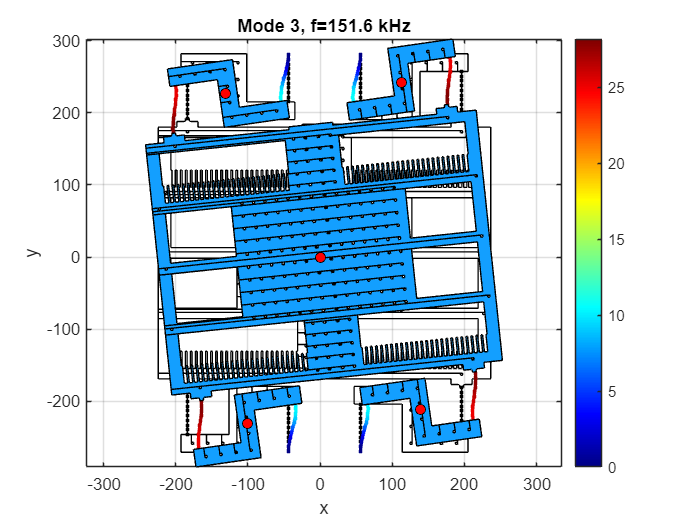

u0   = zeros( obj.Mesh.nDOFs, 1);
Kmpc = obj.tangent_stiffness_and_force(u0);
Mmpc = obj.mass_matrix;

% Eigenvalue problem                                               
n_VMs = 7; % first n_VMs modes with lowest frequency calculated 
[Phi1,om2] = eigs(Kmpc, Mmpc, n_VMs, 'SM');
[om, ind] = sort(sqrt(diag(om2)));
f0 = om/2/pi;

for imod = 1 : 3
    figure
    scale = 20;
    obj.mpc_plot(Phi1(:,imod),scale)
    title(sprintf('Mode %d, f=%.1f kHz',imod,f0(imod)/1000))
end

## Tensor construction

% quadratic and cubic stiffness tensors
[K2_mpc, K3_mpc] = obj.mpc_tensors;

 Building tensors... 		Elapsed time is 0.436018 seconds.


fprintf('non-zero elements in K2: %d / %d \n', nnz(K2_mpc), prod(size(K2_mpc))) %#ok<PSIZE>

non-zero elements in K2: 3530 / 12326391 


fprintf('non-zero elements in K3: %d / %d \n', nnz(K3_mpc), prod(size(K3_mpc))) %#ok<PSIZE>

non-zero elements in K3: 4894 / 2847396321 
